# Impedance Test Sheet

Use this script to check out the reactance and susceptance of a circuit's Z-parameters. The results can then be used to see if the circuit follows Foster's Reactance Theorem.

## Build the Circuit

ck = circuit();
R = 100;
C = 1e-8;
L = 1e-6;

add(ck, [1 2], capacitor(C));
add(ck, [2 3], inductor(L));
add(ck, [2 4], capacitor(C));

setports(ck, [1 4], [3 4]);

## S-Parameters

Create the S-parameter matrix from which all other parameters are derived.

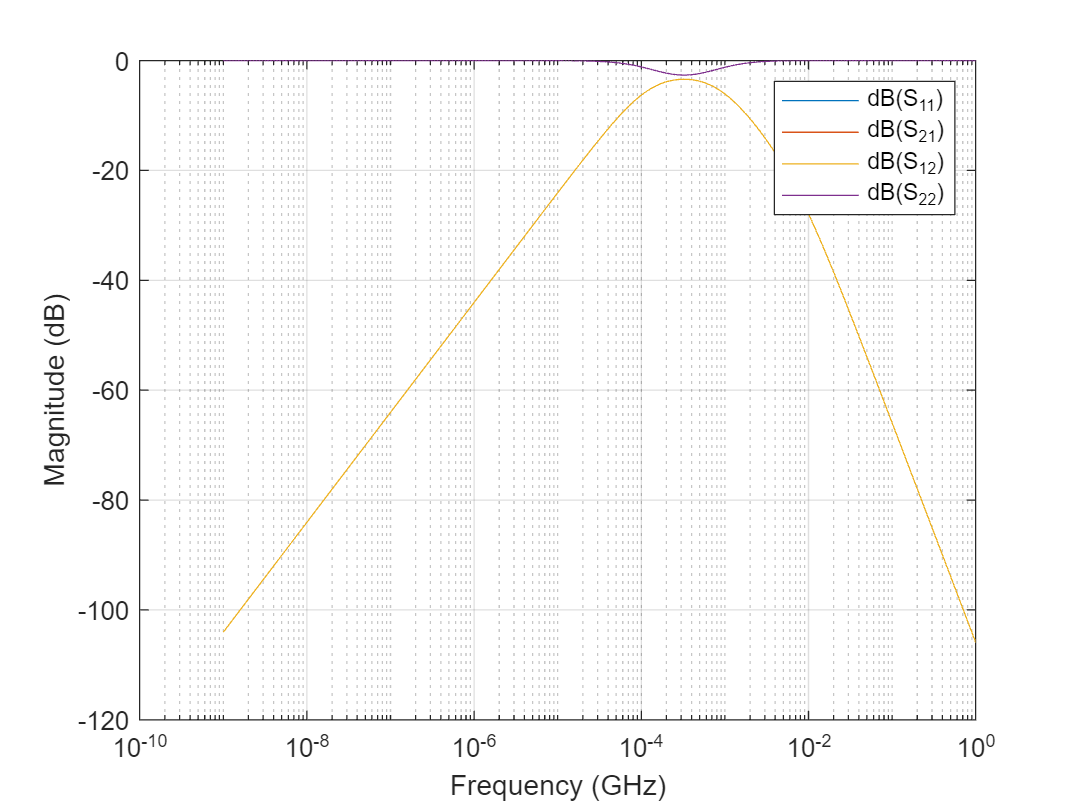

freqs = logspace(0, 9, 500);
freqs1 = logspace(0, 9, 501); % additional frequency for gradient
S = sparameters(ck, freqs);
figure(1);
title('Circuit S-Parameters');
rfplot(S);
xscale('log');

## Z-Parameters

Using the function s2z we transform the S-Parameters into Z, and then graph the reactance versus frequency.

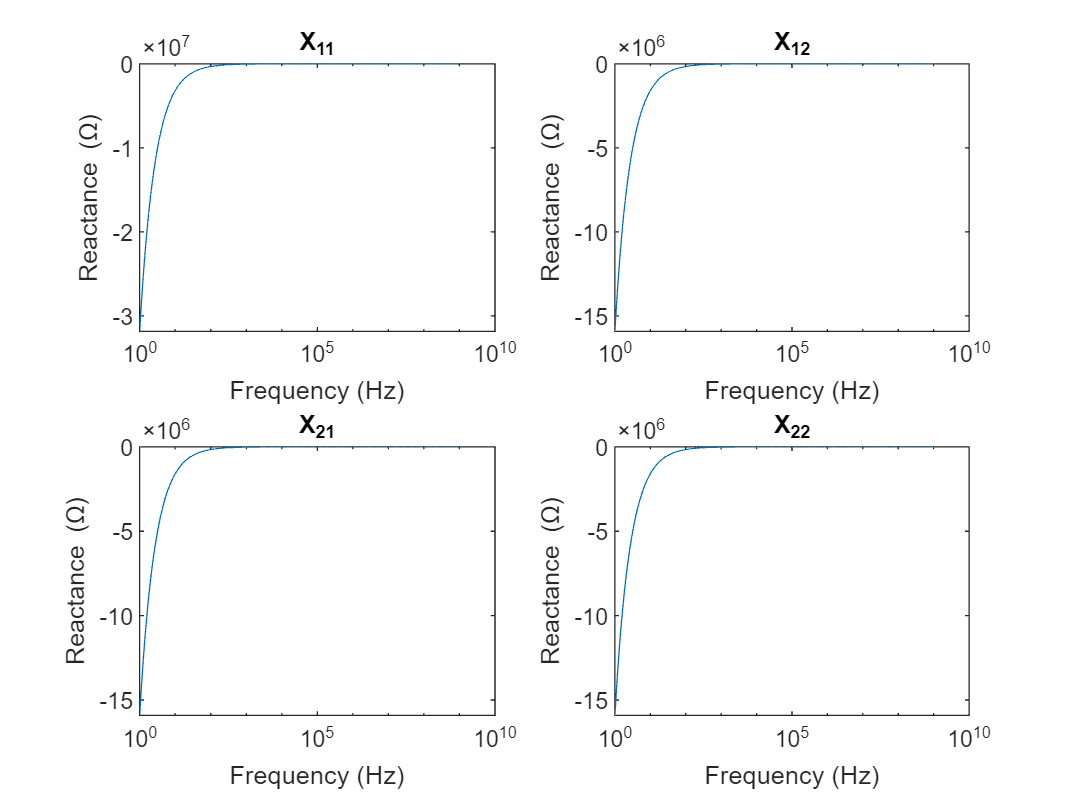

Z = s2z(S.Parameters);
figure(2);

subplot(2, 2, 1);
U = imag(reshape(Z(1, 1, :), 1, []));
plot(freqs, U);
xscale('log');
title('X_1_1');
xlabel('Frequency (Hz)');
ylabel('Reactance (\Omega)');

subplot(2, 2, 2);
U = imag(reshape(Z(1, 2, :), 1, []));
plot(freqs, U);
xscale('log');
title('X_1_2');
xlabel('Frequency (Hz)');
ylabel('Reactance (\Omega)');

subplot(2, 2, 3);
U = imag(reshape(Z(1, 2, :), 1, []));
plot(freqs, U);
xscale('log');
title('X_2_1');
xlabel('Frequency (Hz)');
ylabel('Reactance (\Omega)');

subplot(2, 2, 4);
U = imag(reshape(Z(1, 2, :), 1, []));
plot(freqs, U);
xscale('log');
title('X_2_2');
xlabel('Frequency (Hz)');
ylabel('Reactance (\Omega)');

### Derivative of Reactance

In order to prove Foster's Reactance Theorem, the derivative of reactance with respect to frequency must be greater than or equal to zero for all frequencies of interest.

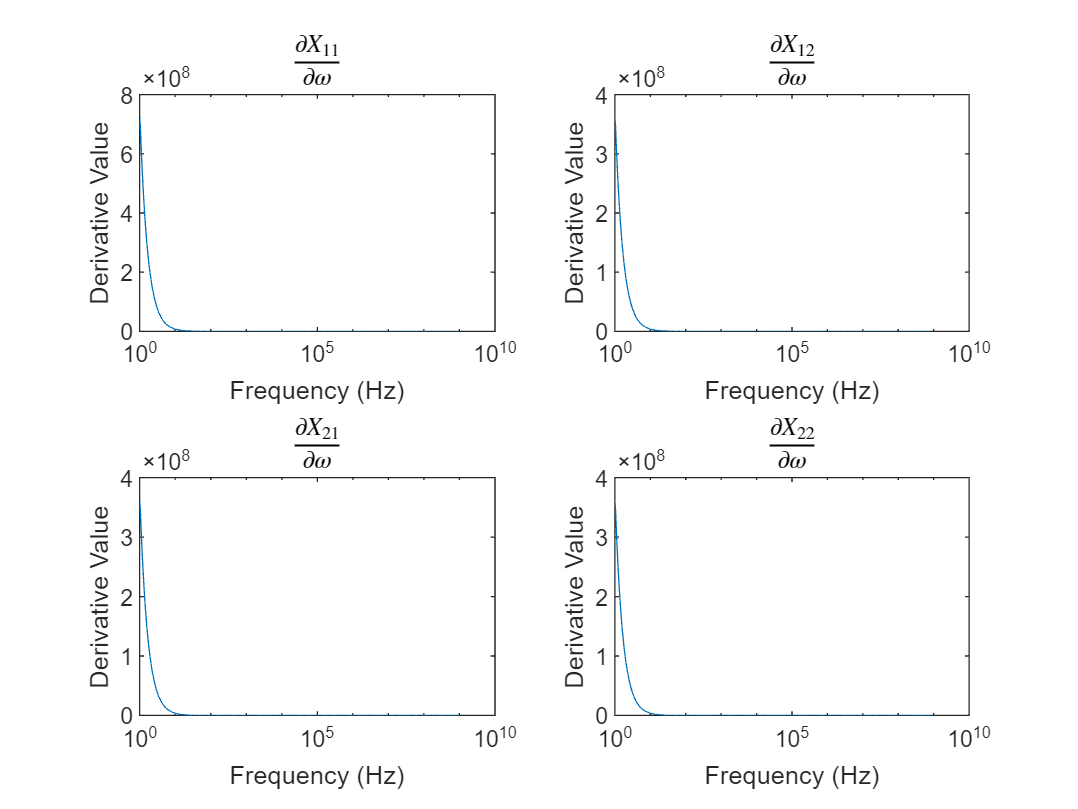

figure(3);

subplot(2, 2, 1);
U = imag(reshape(Z(1, 1, :), 1, []));
plot(freqs, gradient(U, diff(freqs1)));
xscale('log');
title('$\frac {\partial X_{11}}{\partial \omega}$', 'Interpreter', 'latex');
xlabel('Frequency (Hz)');
ylabel('Derivative Value');

subplot(2, 2, 2);
U = imag(reshape(Z(1, 2, :), 1, []));
plot(freqs, gradient(U, diff(freqs1)));
xscale('log');
title('$\frac {\partial X_{12}}{\partial \omega}$', 'Interpreter', 'latex');
xlabel('Frequency (Hz)');
ylabel('Derivative Value');

subplot(2, 2, 3);
U = imag(reshape(Z(2, 1, :), 1, []));
plot(freqs, gradient(U, diff(freqs1)));
xscale('log');
title('$\frac {\partial X_{21}}{\partial \omega}$', 'Interpreter', 'latex');
xlabel('Frequency (Hz)');
ylabel('Derivative Value');

subplot(2, 2, 4);
U = imag(reshape(Z(2, 2, :), 1, []));
plot(freqs, gradient(U, diff(freqs1)));
xscale('log');
title('$\frac {\partial X_{22}}{\partial \omega}$', 'Interpreter', 'latex');
xlabel('Frequency (Hz)');
ylabel('Derivative Value');

## Y-Parameters

Foster's Reactance Theorem must also hold for the admittance of the circuit as well. However, the admittance may not always exist as the circuit may not have an inverse.

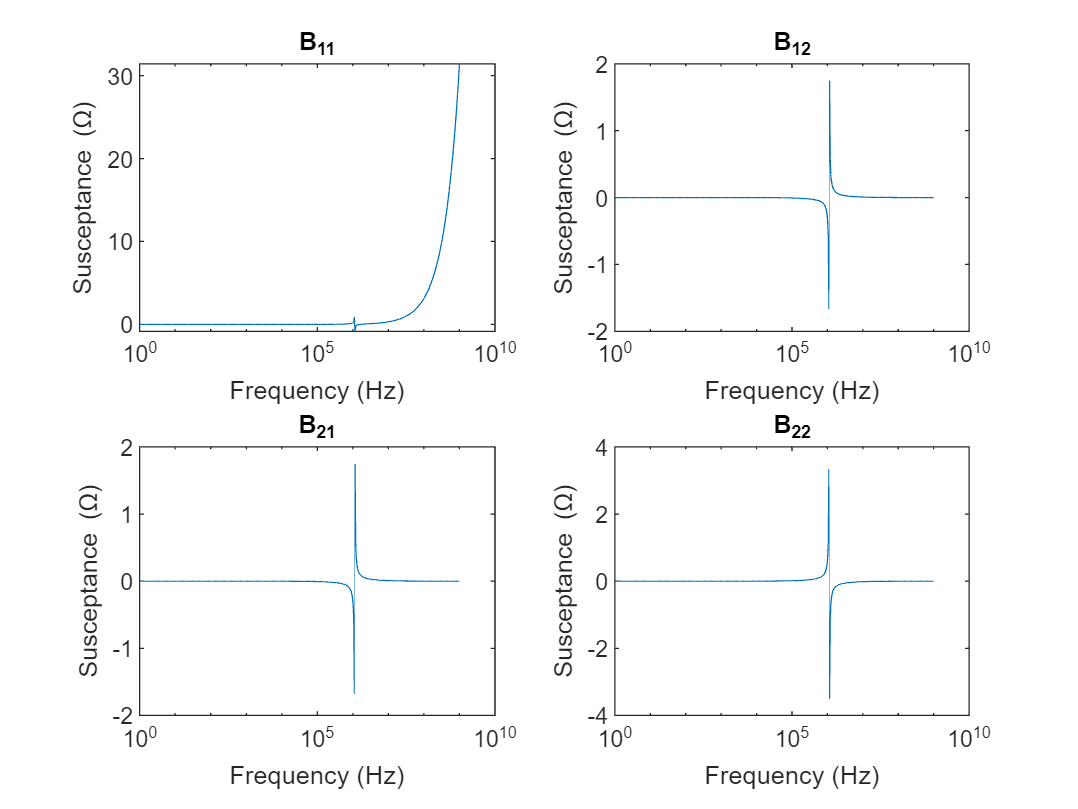

Y = s2y(S.Parameters);
figure(4);

subplot(2, 2, 1);
U = imag(reshape(Y(1, 1, :), 1, []));
plot(freqs, U);
xscale('log');
title('B_1_1');
xlabel('Frequency (Hz)');
ylabel('Susceptance (\Omega)');

subplot(2, 2, 2);
U = imag(reshape(Y(1, 2, :), 1, []));
plot(freqs, U);
xscale('log');
title('B_1_2');
xlabel('Frequency (Hz)');
ylabel('Susceptance (\Omega)');

subplot(2, 2, 3);
U = imag(reshape(Y(2, 1, :), 1, []));
plot(freqs, U);
xscale('log');
title('B_2_1');
xlabel('Frequency (Hz)');
ylabel('Susceptance (\Omega)');

subplot(2, 2, 4);
U = imag(reshape(Y(2, 2, :), 1, []));
plot(freqs, U);
xscale('log');
title('B_2_2');
xlabel('Frequency (Hz)');
ylabel('Susceptance (\Omega)');

### Derivative of Susceptance

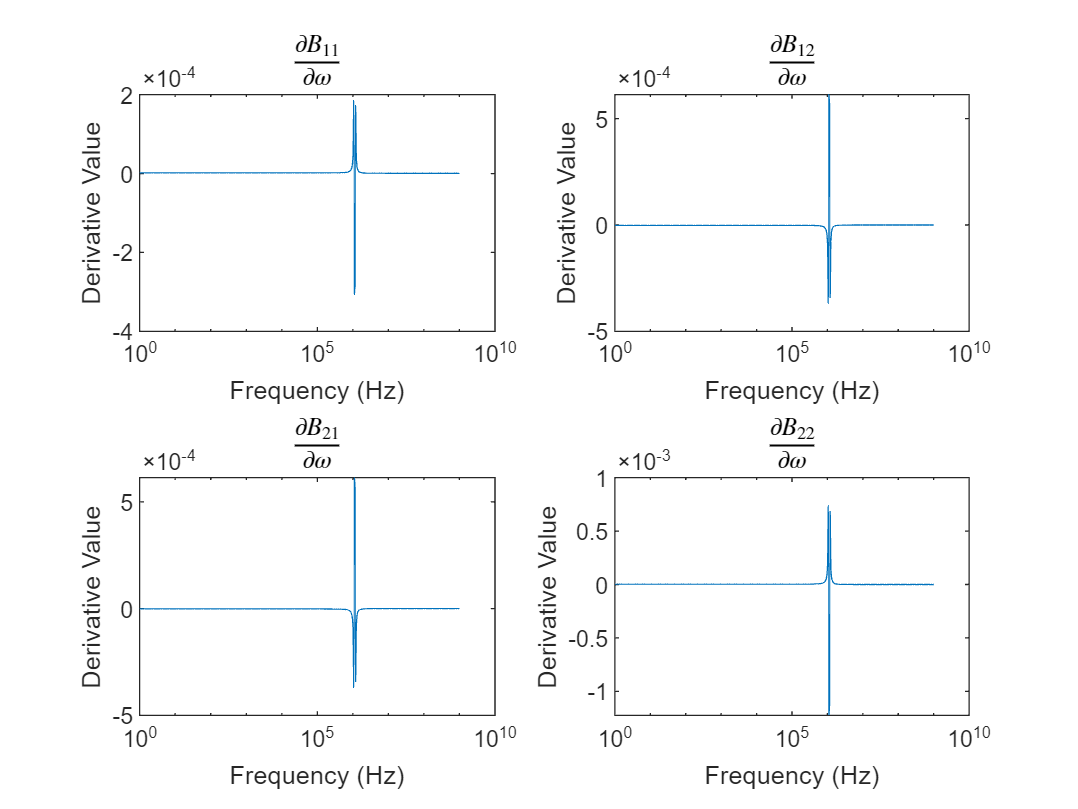

figure(5);

subplot(2, 2, 1);
U = imag(reshape(Y(1, 1, :), 1, []));
plot(freqs, gradient(U, diff(freqs1)));
xscale('log');
title('$\frac {\partial B_{11}}{\partial \omega}$', 'Interpreter', 'latex');
xlabel('Frequency (Hz)');
ylabel('Derivative Value');

subplot(2, 2, 2);
U = imag(reshape(Y(1, 2, :), 1, []));
plot(freqs, gradient(U, diff(freqs1)));
xscale('log');
title('$\frac {\partial B_{12}}{\partial \omega}$', 'Interpreter', 'latex');
xlabel('Frequency (Hz)');
ylabel('Derivative Value');

subplot(2, 2, 3);
U = imag(reshape(Y(2, 1, :), 1, []));
plot(freqs, gradient(U, diff(freqs1)));
xscale('log');
title('$\frac {\partial B_{21}}{\partial \omega}$', 'Interpreter', 'latex');
xlabel('Frequency (Hz)');
ylabel('Derivative Value');

subplot(2, 2, 4);
U = imag(reshape(Y(2, 2, :), 1, []));
plot(freqs, gradient(U, diff(freqs1)));
xscale('log');
title('$\frac {\partial B_{22}}{\partial \omega}$', 'Interpreter', 'latex');
xlabel('Frequency (Hz)');
ylabel('Derivative Value');